clear all
format shortG

filename = 'logFreeFlight15sec.txt';
% remember: cd 'C:\Users\marti\OneDrive - Danmarks Tekniske Universitet\DTU\2-rotor drone Bachelor'
%9.3-23.2
startTime=9.3;
endTime=23.2;
rawimport = importdata(filename);
rawdata = rawimport.data

rawdata =           6.1            2            0        99.36       -0.175            0        0.465        707.9        -25.1       -302.9       -205.5       0.9144     -0.21981     -0.00666        18.48       -0.401
        46.15            2            0       99.544       -0.175            0        0.465        703.5          1.5       -253.7       -137.1       0.9398      -0.2228      0.91744       17.168        0.543
        86.14            2            0       99.544       -0.175            0        0.465        703.6         -1.8          -10          250       0.9398     -0.06526       1.5859      -10.207        0.528
       126.11            2            0       99.636       -0.105            0        0.155          710        -33.1         -4.1        244.5       0.9144      0.05618         1.91      -6.2071       -0.432
       166.11            2            0       99.636       -0.105        0.035        0.465        707.3        -10.6         -7.4         -250       0.91


t = rawdata(:,1)./1000; % 1     Time (s)
arm_state = rawdata(:,2); % 2     Arm state (init, disarmed, armed, fail)
flight_state = rawdata(:,3); % 3     Flight state (on ground, starting, flight, landing)
h_ref = rawdata(:,4); % 4     Height ref (thrust ref)
r_ref = rawdata(:,5); % 5     Roll ref (deg)
p_ref = rawdata(:,6); % 6     Pitch ref (deg)
y_ref = rawdata(:,7); % 7     Yaw ref (deg/s)
h_mixer = rawdata(:,8); % 8     Height value to mixer (thrust ref) o/oo
r_mixer = rawdata(:,9); % 9     Roll value to mixer o/oo
p_mixer = rawdata(:,10); % 10    Pitch value to mixer o/oo
y_mixer = rawdata(:,11); % 11    Yaw value to mixer o/oo
h_pos = rawdata(:,12); % 12    Height position (m) filtered 
r_pos = rawdata(:,13); % 13    Roll angle (deg)
p_pos = rawdata(:,14); % 14    Pitch angle (deg)
y_vel = rawdata(:,15); % 15    Yaw velocity (deg/s)
h_vel = rawdata(:,16); % 16    Height velocity (m/s) 
%new ref input

%Sorting all according to time t:
[t, idx] = sort(t);
r_pos = r_pos(idx);
r_ref = r_ref(idx);
p_pos = p_pos(idx);
p_ref = p_ref(idx);
y_vel = y_vel(idx);
y_ref = y_ref(idx);
h_pos = h_pos(idx);
h_vel = h_vel(idx);
h_ref = h_ref(idx);

time_Idx= all([t>=startTime,t<=endTime]') %finding right time interval

time_Idx = 1×5528 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


%plot(time_Idx)
r_pos = r_pos(time_Idx);
r_ref = r_ref(time_Idx);
p_pos = p_pos(time_Idx);
p_ref = p_ref(time_Idx);
y_vel = y_vel(time_Idx);
y_ref = y_ref(time_Idx);
h_pos = h_pos(time_Idx);
h_vel = h_vel(time_Idx);
h_ref = h_ref(time_Idx);
time=t(time_Idx)

time =        9.3261
       9.3662
       9.4061
       9.4461
       9.4861
       9.5261
       9.5662
       9.6062
       9.6462
       9.6861


plot(time,[r_pos,r_ref])
legend("Roll position","Roll position ref")
title('Roll')
title("Roll Position", "Free flight")
xlabel('Time [s]');
ylabel('Roll position [deg]') 
grid on
%ylim([-60, 60])
%xlim([-60, 60])
length(r_pos)

ans =         2057


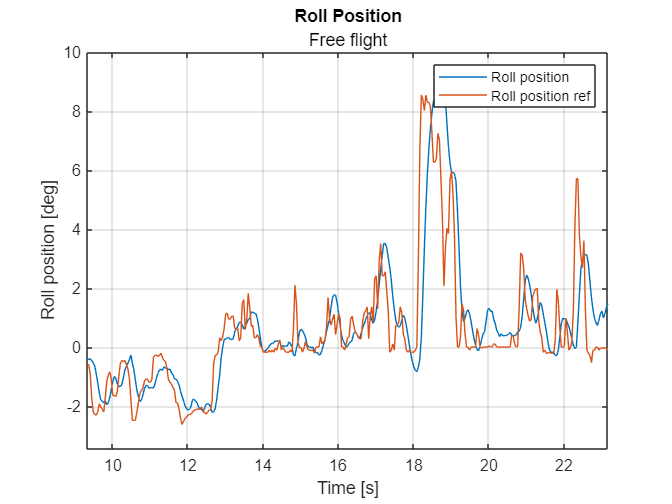

xlim tight
ylim padded

lgd = legend;

[time_uniqe,idx,~]=unique(time)%uniqe time values

time_uniqe =        9.3261
       9.3662
       9.4061
       9.4461
       9.4861
       9.5261
       9.5662
       9.6062
       9.6462
       9.6861


idx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


r_pos = r_pos(idx);
r_ref = r_ref(idx);
p_pos = p_pos(idx);
p_ref = p_ref(idx);
y_vel = y_vel(idx);
y_ref = y_ref(idx);
h_pos = h_pos(idx);
h_vel = h_vel(idx);
h_ref = h_ref(idx);

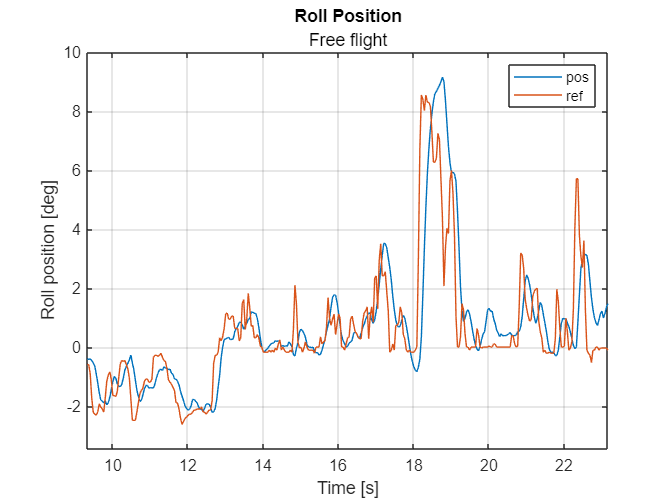

clf
plot(time_uniqe,[r_pos,r_ref])
legend("pos","ref")
title("Roll Position", "Free flight")
xlabel('Time [s]');
ylabel('Roll position [deg]') 
grid on
xlim tight
ylim padded

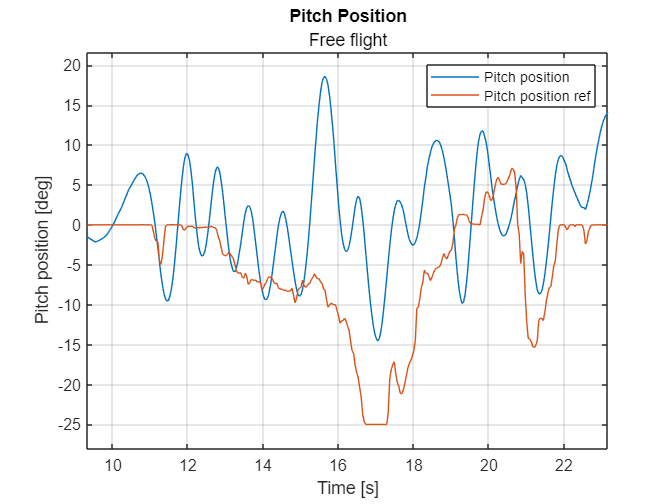


plot(time_uniqe,[p_pos,p_ref])
legend("Pitch position","Pitch position ref")
title("Pitch Position", "Free flight")
xlabel('Time [s]');
ylabel('Pitch position [deg]') 
grid on
xlim tight
ylim padded

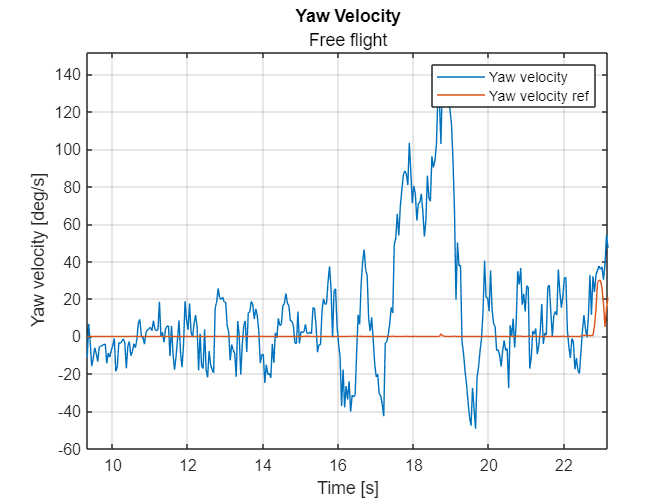


plot(time_uniqe,[y_vel,y_ref])
legend("Yaw velocity","Yaw velocity ref")
title("Yaw Velocity", "Free flight")
xlabel('Time [s]');
ylabel('Yaw velocity [deg/s]')
grid on
xlim tight
ylim padded

input1=[r_ref,p_ref,y_ref]

input1 =        -0.595            0            0
       -0.595            0            0
        -0.91            0            0
       -1.715            0            0
       -2.205            0            0
       -2.275            0            0
        -2.31            0            0
       -2.205            0            0
       -1.925            0            0
        -2.03            0            0


output1=[r_pos,p_pos,y_vel]

output1 =       -0.4003      -1.4674      -11.332
     -0.41523      -1.6502       6.7304
     -0.40178       -1.762      -3.0196
     -0.46255      -1.8658      -15.895
      -0.5348      -2.0015      -11.645
     -0.63885      -2.1481      -6.0196
     -0.91037      -2.1149      -9.0821
      -1.2098      -2.0413      -13.457
      -1.5462      -1.9434      -5.8321
      -1.7951       -1.846      -5.0821


%save("filteredFlightData.mat","input1","output1")

%now you can use systemIdentification in terminal

%clear all
%cd("C:\Users\User\OneDrive\DTU\DTU 4-2-2020\DTU\6. semester\bachelor projekt\Flight data")
%load("filteredFlightData.mat")

%input1
%output1
%FemteOrdensSS

%eig(ss5)
%step(ss5)
%FemteOrdensSS=ss(ss5.A,ss5.B,ss5.C,0,'InputName',{'InputRoll','InputPitch','InputYaw'},'OutputName',{'Roll','Pitch','Yaw'})
%step(FemteOrdensSS)
%save("filteredFlightData.mat","FemteOrdensSS","input1","output1")

%step(ss10)
